# **Laborator 3 - Condiționarea unei probleme**

#### P1.W. **Fie sistemul (exemplul este datorat lui Wilson):**

A = [10, 7, 8, 7;
    7, 5, 6, 5;
    8, 6, 10, 9;
    7, 5, 9, 10];
B = [32; 23; 33; 31];
X = A \ B;

(a) Perturbăm membrul drept:

% Matricea perturbată:
Bp = [32.1; 22.9; 33.1; 30.9];

fprintf("Perturbarea membrului drept cu matricea:");

Perturbarea membrului drept cu matricea:

disp(Bp);

   32.1000
   22.9000
   33.1000
   30.9000




Xp1 = A \ Bp;

% Eroarea la intrare:
err1_in = norm(Bp - B) / norm(B);
fprintf("Eroarea la intrare: %f", err1_in);

Eroarea la intrare: 0.003332


% Eroarea la ieșire:
err1_out = norm(Xp1 - X) / norm(X);
fprintf("Eroarea la ieșire: %f", err1_out);

Eroarea la ieșire: 8.198475


% Raportul erorilor:
err_raport1 = err1_out / err1_in;
fprintf("Raportul erorilor: %f", err_raport1);

Raportul erorilor: 2460.567236

(b) Perturbăm matricea sistemului:

% Matricea perturbată:
Ap = [10, 7, 8.1, 7.2;
    7.08, 5.04, 6, 5;
    8, 5.98, 9.89, 9;
    6.99, 4.99, 9, 9.98];

fprintf("Perturbarea matricii sistemului cu matricea:");

Perturbarea matricii sistemului cu matricea:

disp(Ap);

   10.0000    7.0000    8.1000    7.2000
    7.0800    5.0400    6.0000    5.0000
    8.0000    5.9800    9.8900    9.0000
    6.9900    4.9900    9.0000    9.9800




Xp2 = Ap \ B;

% Eroarea la intrare:
err2_in = norm(Ap - A) / norm(A);
fprintf("Eroarea la intrare: %f", err2_in);

Eroarea la intrare: 0.007621


% Eroarea la ieșire:
err2_out = norm(Xp2 - X) / norm(X);
fprintf("Eroarea la ieșire: %f", err2_out);

Eroarea la ieșire: 81.984755


% Raportul erorilor:
err_raport2 = err2_out / err2_in;
fprintf("Raportul erorilor: %f", err_raport2);

Raportul erorilor: 10757.882995

#### P2.H. Să se studieze condiționarea matricei Hilbert Hn în raport cu norma euclidiană, n = 10..15.

% The Hilbert matrix is a notable example of a poorly conditioned matrix.
% The elements of Hilbert matrices are given by H(i, j) = 1 / (i + j – 1).

start = 10;
finish = 15;

cn = zeros(1, finish - start);

for n = start : finish
    H = hilb(n);
    cn(n - start + 1) = cond(H);        % The 2-norm condition number
end

fprintf("Condiționarea Hilbert:");

Condiționarea Hilbert:

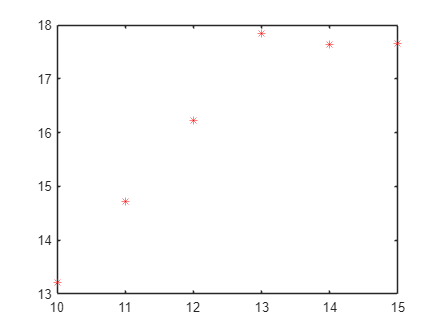

plot(start : finish, log10(cn), 'r*')

#### P3. (a) Să se studieze condiționarea matricei Vandermonde Vn(t), pentru tk = -1 + k*2/n, n = 10..15, în raport cu norma Cebîșev.

####       (b) Aceeași întrebare pentru tk = 1 / k, k = 1..n și n = 10..15.

warning("off");

% (a) Pentru tk = -1 + k * 2 / n:
start = 10;
finish = 15;
cn_a = zeros(1, finish - start);

for n = start : finish
    k = linspace(-1, 1, n);
    t = -1 + 2 .* (k./n);
    V = vander(t);
    cn_a(n - start + 1) = cond(V, Inf); % Cond în funcție de norma Cebîșev
end

% b) Pentru tk = 1 / k:
cn_b = zeros(1, finish - start);

for n = start : finish
    k = 1 : n;
    o = ones(1, n);
    t = o./k;
    v = vander(t);
    cn_b(n - start + 1) = cond(v, Inf);
end

fprintf("Condiționarea Vandermonde:");

Condiționarea Vandermonde:

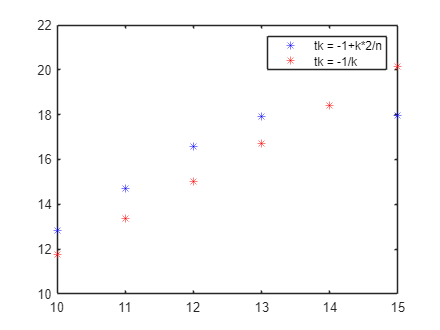

plot(start : finish, log10(cn_a), '*b', start : finish, log10(cn_b), 'r*');
legend("tk = -1+k*2/n", "tk = -1/k");

#### P4. Să se studieze teoretic și experimental condiționarea problemei determinării rădăcinilor ecuației polinomiale, cunoscându-se coeficienții. 

warning("off");

% Pentru (x-1)(x-2)...(x-n) = 0:

my_roots1 = [1 : 20]; 
polynom1 = poly(my_roots1);
fprintf("Numerele de condiționare pentru polinomială:");

Numerele de condiționare pentru polinomială:

disp(cond_pol(polynom1, my_roots1));

   1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0069    0.0392    0.1682    0.5557    1.4194    2.8523    4.4307    5.4010    5.0243    3.5438    1.8121    0.6380    0.1378    0.0138



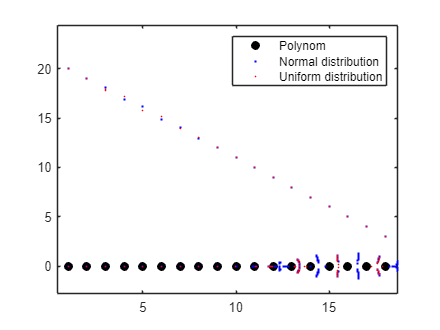


figure(1);
roots1_length = length(my_roots1);
h = plot(my_roots1, zeros(1, roots1_length), 'k.');

set(h, 'Markersize', 20);

hold on;

% Perturbăm polinomul folosind:
for i = 1 : 20

    % 1. Distribuția normală:
    polynom1_normrnd = polynom1 + normrnd(0, 1E-10, 1, length(polynom1));
    roots1_normrnd = roots(polynom1_normrnd);
    h2 = plot(roots1_normrnd, 'b.');

    hold on;

    set(h2, 'Markersize', 4);
    
    % 2. Distribuția uniformă:
    polynom1_unifrnd = polynom1 + unifrnd(0, 1E-10, 1, length(polynom1));
    roots1_unifrnd = roots(polynom1_unifrnd);
    
    h3 = plot(roots1_unifrnd, 'r.');

    hold on;

    set(h3, 'Markersize', 2);
end

legend("Polynom", "Normal distribution", "Uniform distribution");

hold off;



% Pentru a^k = 2^-k
polynom2 = 2.^-(1 : 20);
fprintf("Numerele de condiționare pentru funcția a^k = 2^(-k):");

Numerele de condiționare pentru funcția a^k = 2^(-k):

disp(cond_pol(polynom2));

    0.2972
    0.2972
    0.5871
    0.5871
    0.8626
    0.8626
    1.1168
    1.1168
    1.9000
    1.8766
    1.8766
    1.8070
    1.8070
    1.6929
    1.6929
    1.5371
    1.5371
    1.3435
    1.3435



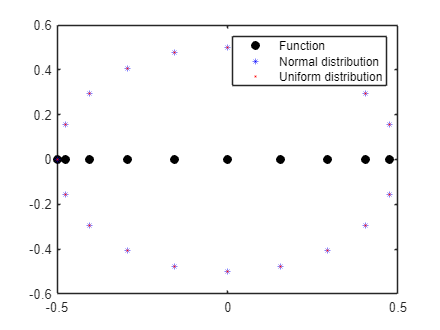

my_roots2 = roots(polynom2);

figure(2);
roots2_length = length(my_roots2);
h = plot(my_roots2, zeros(1, roots2_length), 'k.');

set(h, 'Markersize', 20);

hold on;

% Perturbăm funcția folosind:
for i = 1 : 20

    % 1. Distribuția normală:
    polynom2_normrnd = polynom2 + normrnd(0, 1E-10, 1, length(polynom2));
    roots2_normrnd = roots(polynom2_normrnd);
    
    h2 = plot(roots2_normrnd, 'b*');
    
    hold on;
    
    set(h2, 'Markersize', 4);
    
    % 2. Distribuția uniformă:
    polynom2_unifrnd = polynom2 + unifrnd(0, 1E-10, 1, length(polynom2));
    roots2_unifrnd = roots(polynom2_unifrnd);
    
    h3 = plot(roots2_unifrnd, 'r*');
    
    hold on;
    
    set(h3, 'Markersize', 2);
end

legend("Function", "Normal distribution", "Uniform distribution");

hold off;